clc;
clear all; close all;

load('Prob4.mat');

## Prob 4a. Bode Plot

disp('>> Prob 4a. Root locus');

>> Prob 4a. Root locus


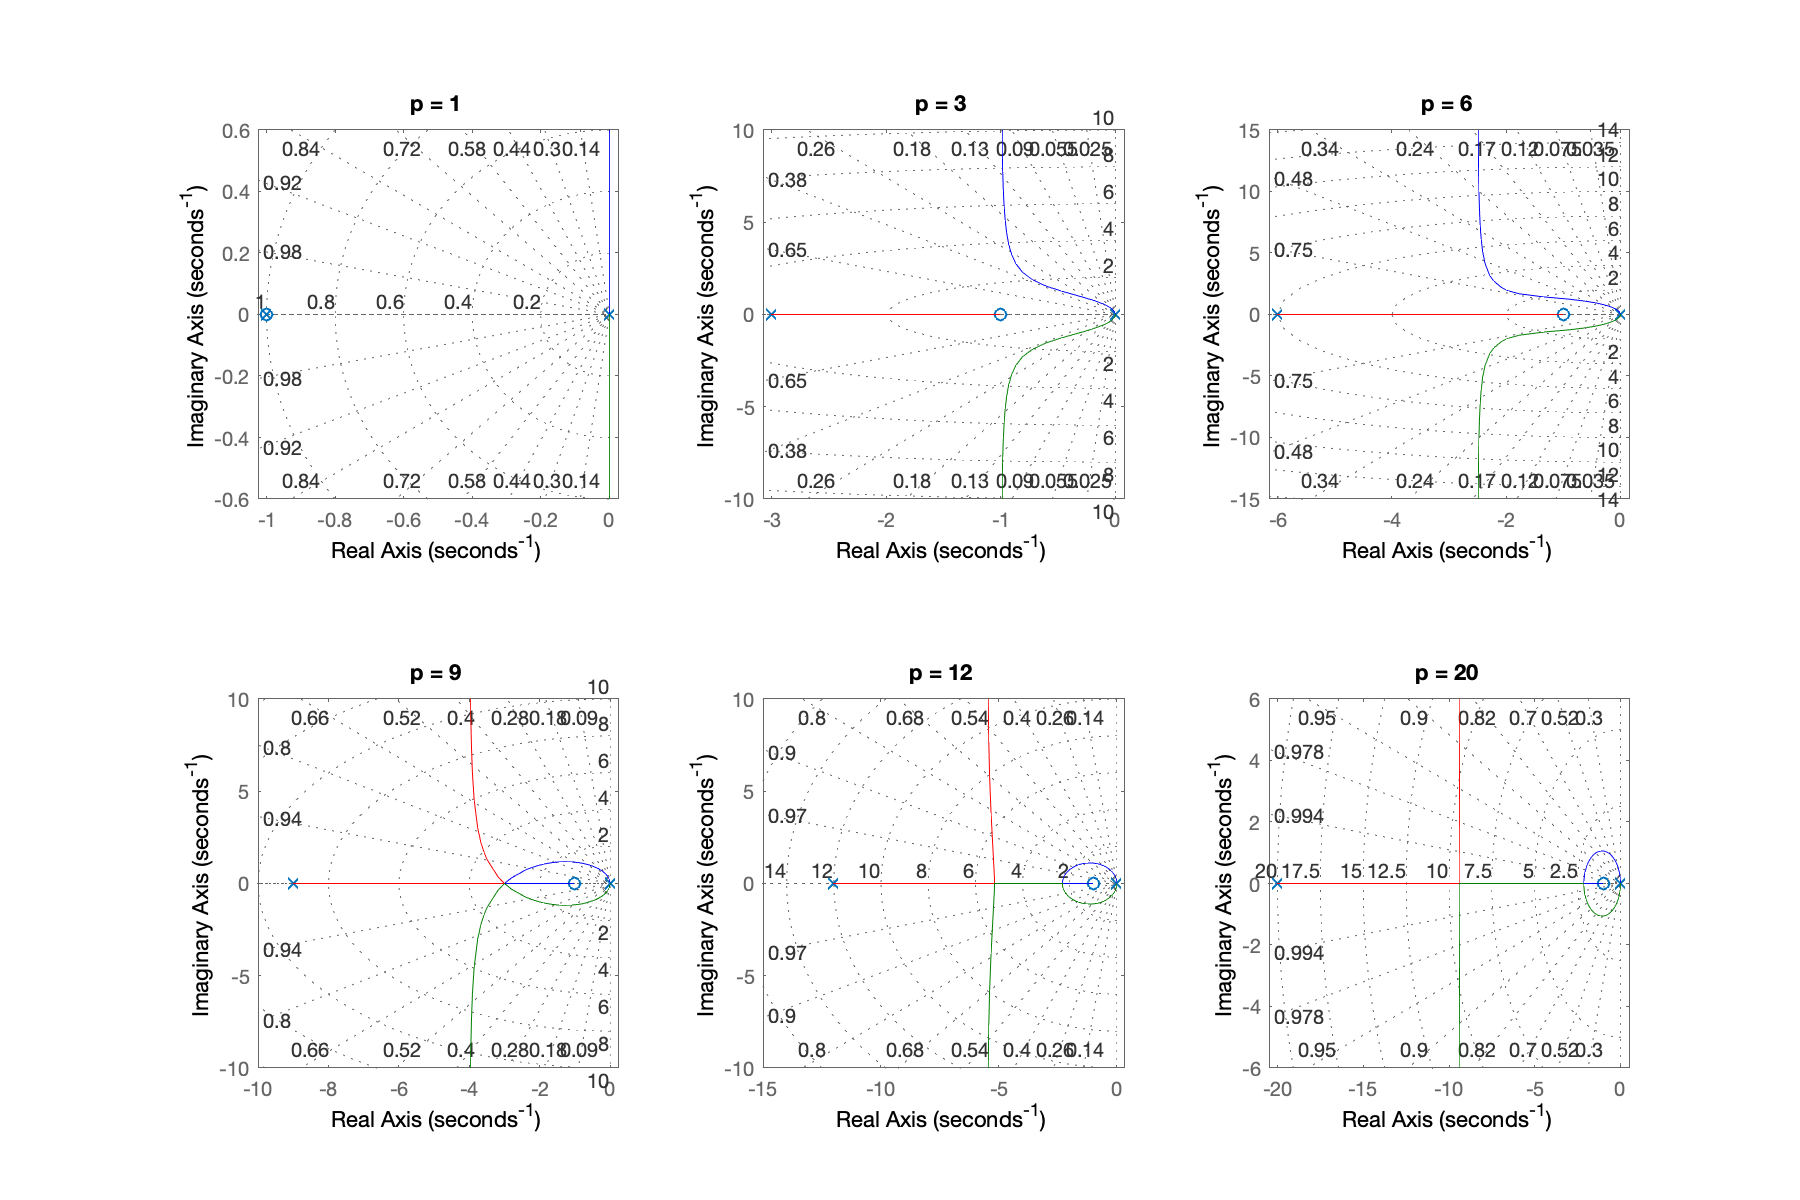


p = [1 3 6 9 12 20];

figure(1)
set(gcf,'position', [0, 0, 900, 600]);

for i=1:length(p)
    G = tf([1],[1 0 0]);    % 1/s^2
    C = tf([1 1],[1 p(i)]); % (s+1)/(s+p)

    subplot(2,3,i)
    rlocus(G*C); grid on;
    title(['p = ' num2str(p(i)) ''])
end


disp(repmat('=',1,80));

## Prob 4b. to 4d. Designing a Compensator

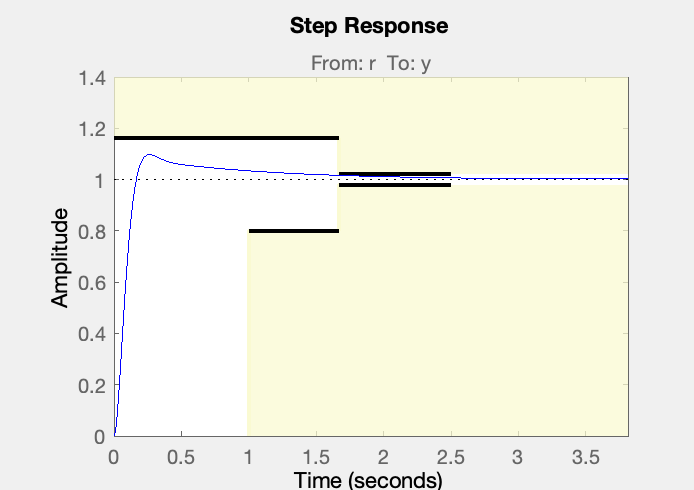

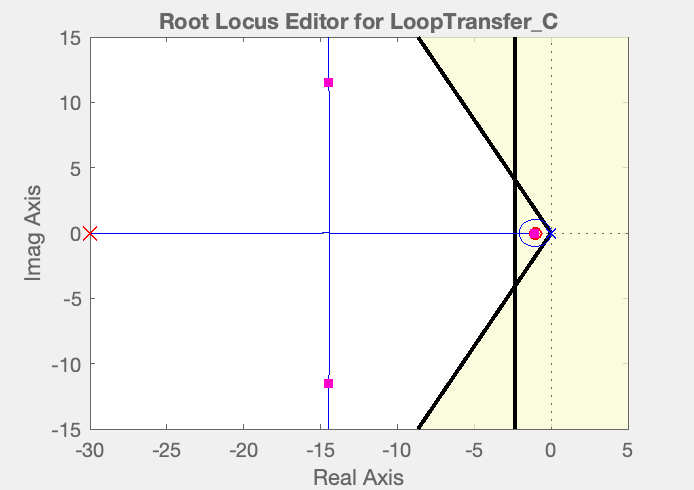

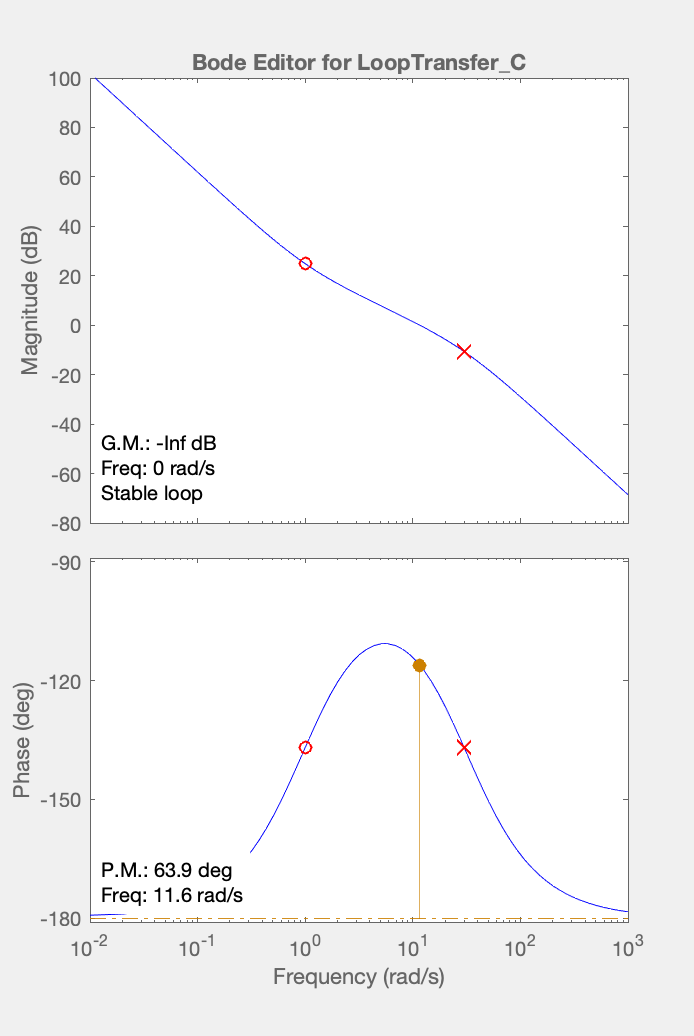

% Design from the beginning.
% sisotool(G, C);

% Or load the saved file.
sisotool('Prob4.mat');